# Creation of records from measurement

## Data collection settings

Data has been colected using phyphox.

Settings for experiment: 

- sampling 200Hz

Measurements:

- Gyroscope

- Linear acceleration

We measured 60 seconds of activities for each participant, the activities were:

- Standing still

- Walking

- Squating

- Tip rising

Files were saved in excel format and sent over email. Excel files were imported using the import data wizard from matlab and saved to mat files containing a table for gyroscope measurements and a table for linear acceleration measurements.

Files were saved per each participant in the recording session:

- janaka.mat

- daniel.mat

- gustavo.mat

load('janaka.mat');
load('daniel.mat');
load('gustavo.mat');

We plot each activity for each participant so we can trim the data for each activity, we did abrupt movements when we changed the activity.

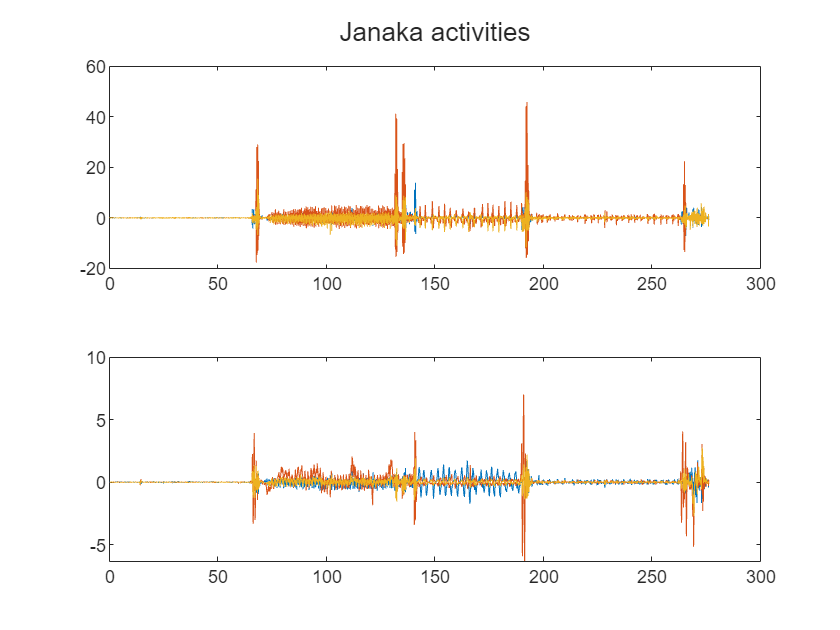

plotMeasurementTables(janaka_linearacceleration, janaka_gyroscope,'Janaka activities');

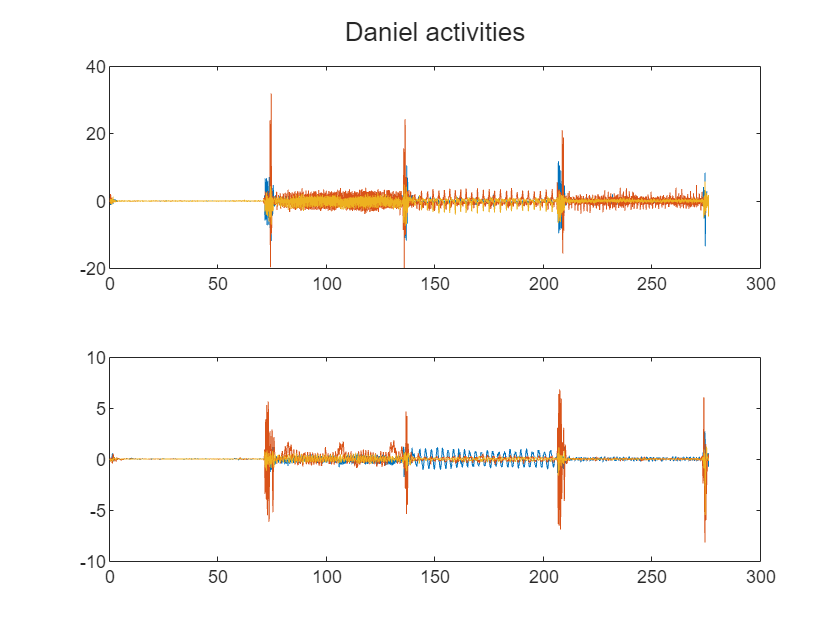

plotMeasurementTables(daniel_linearacceleration, daniel_gyroscope, 'Daniel activities');

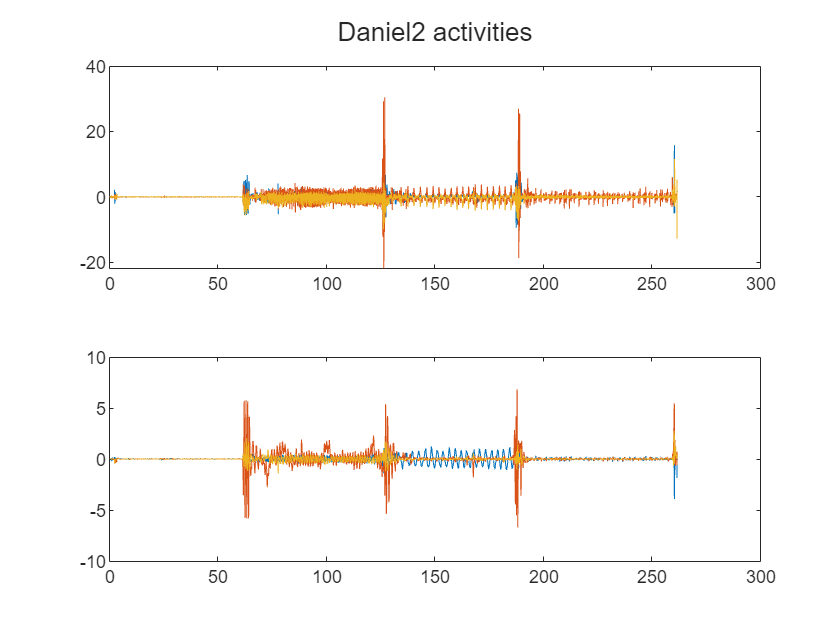

plotMeasurementTables(daniel2_linearacceleration, daniel2_gyroscope, 'Daniel2 activities');

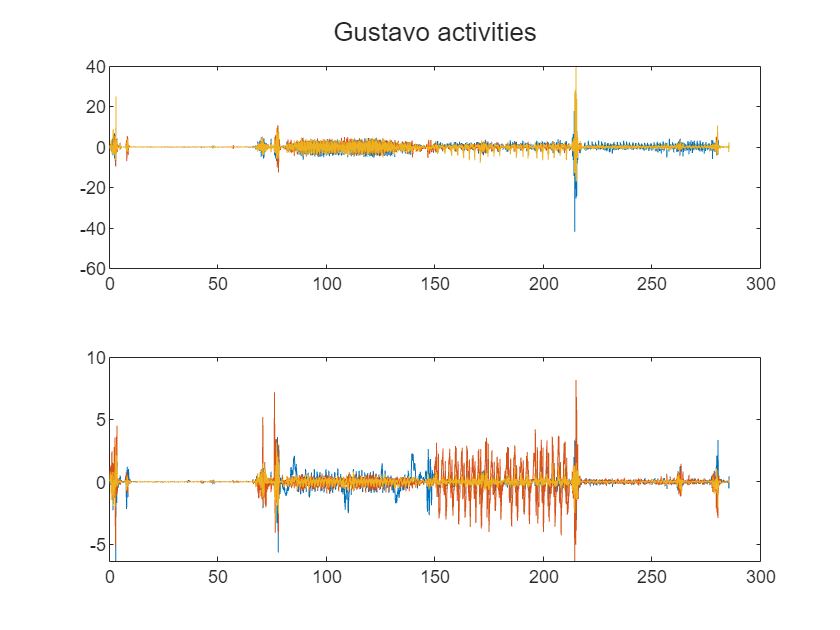

plotMeasurementTables(gustavo_linearacceleration, gustavo_gyroscope, 'Gustavo activities');

We have sampled it at 200Hz, that means 200 samples each second. We collected 60 seconds of data, so we want to collect 200x60 seconds.

% create instances of PersonRecordedObject for each person
janaka = PersonRecordedObject('Janaka', ...
                              getActivityTables(janaka_linearacceleration,janaka_gyroscope,0,60), ...       %standing
                              getActivityTables(janaka_linearacceleration,janaka_gyroscope,70,130),...      %walking
                              getActivityTables(janaka_linearacceleration, janaka_gyroscope,142,189),...    %knee bending
                              getActivityTables(janaka_linearacceleration, janaka_gyroscope,200,260));      %tip rising

gustavo = PersonRecordedObject('Gustavo', ...
                              getActivityTables(gustavo_linearacceleration,gustavo_gyroscope,10,66), ...    %standing
                              getActivityTables(gustavo_linearacceleration,gustavo_gyroscope,80,140),...    %walking
                              getActivityTables(gustavo_linearacceleration, gustavo_gyroscope,150,210),...  %knee bending
                              getActivityTables(gustavo_linearacceleration, gustavo_gyroscope,217,277));    %tip rising


daniel = PersonRecordedObject('Daniel', ...
                              getActivityTables(daniel_linearacceleration,daniel_gyroscope,10,70), ...      %standing
                              getActivityTables(daniel_linearacceleration,daniel_gyroscope,76,135),...      %walking
                              getActivityTables(daniel_linearacceleration, daniel_gyroscope,138,205),...    %knee bending
                              getActivityTables(daniel_linearacceleration, daniel_gyroscope,211,272));      %tip rising


daniel2 = PersonRecordedObject('Daniel2', ...
                              getActivityTables(daniel2_linearacceleration,daniel2_gyroscope,4,60), ...     %standing
                              getActivityTables(daniel2_linearacceleration,daniel2_gyroscope,65,125),...    %walking
                              getActivityTables(daniel2_linearacceleration, daniel2_gyroscope,129,186),...  %knee bending
                              getActivityTables(daniel2_linearacceleration, daniel2_gyroscope,191,258));    %tip rising

Now we have 4 objects, they contain recordings for all activities

- janaka

- gustavo

- daniel

- daniel2

We then extract features from each person and merge all features in a single table

% get features table for each person, also get labels from each activity
[features_table_gustavo, activity_labels_gustavo] = getFeaturesFromPerson(gustavo);
[features_table_janaka, activity_labels_janaka] = getFeaturesFromPerson(janaka);
[features_table_daniel, activity_labels_daniel] = getFeaturesFromPerson(daniel);
[features_table_daniel2, activity_labels_daniel2] = getFeaturesFromPerson(daniel2);

% merge all features and activity labels into a single table (one for
% features one for labels)
% at this point we don't need to who was doing the activity, but what
% activity is for each feature
features_table = vertcat(features_table_gustavo, ...
                         features_table_janaka, ...
                         features_table_daniel, ...
                         features_table_daniel2);

activity_labels = vertcat(activity_labels_gustavo, ...
                          activity_labels_janaka, ...
                          activity_labels_daniel, ...
                          activity_labels_daniel2);

% add activity labels to the features table
features_table.activity_labels = activity_labels;

